# Consideraciones para el tercer trabajo grupal

Herramientas Matemáticas para el Manejo de la Información

Sesión 15 - 21 de mayo de 2026

# Generadores de secuencias discretas con LRD

Para la generación sintética de secuencias discretas que exhiban LRD se disponen de dos funciones: `wfbm`, propietaria de MATLAB y que genera señales basadas en el movimiento browniano fraccional; y betamwm, codificada para implementar una cascada binomial conservativa. Se recomienda estudiar ambos conceptos en la literatura especializada.

## betamwm

La función `betamwm` se puede emplear para generar secuencias discretas multifractales. Con tal propósito, se sugiere:

- Escoger cualquier valor real positivo para el primer parámetro, $U_{00}$. Su valor no va a afectar la LRD o la multifractalidad.

- El segundo parámetro es el exponente de una potencia de dos. Por ejemplo, con 10 se generaría una secuencia con 1024 valores. Se recomienda usar un exponente de por lo menos 14.

- El tercer parámetro es el de Hurst y debe ser un número real que se encuentre en el intervalo $(0.5,1)$.

Por ejemplo:

Uoo = 1; % Cualquier número real positivo es válido.
H = 0.6; % Parámetro de Hurst seleccionado. 0.5<H<1.
exponente = 14; % Exponente de la potencia de 2. Mínimo 14 para tener más de 10000 datos.
longitud = 2^exponente

longitud = 16384

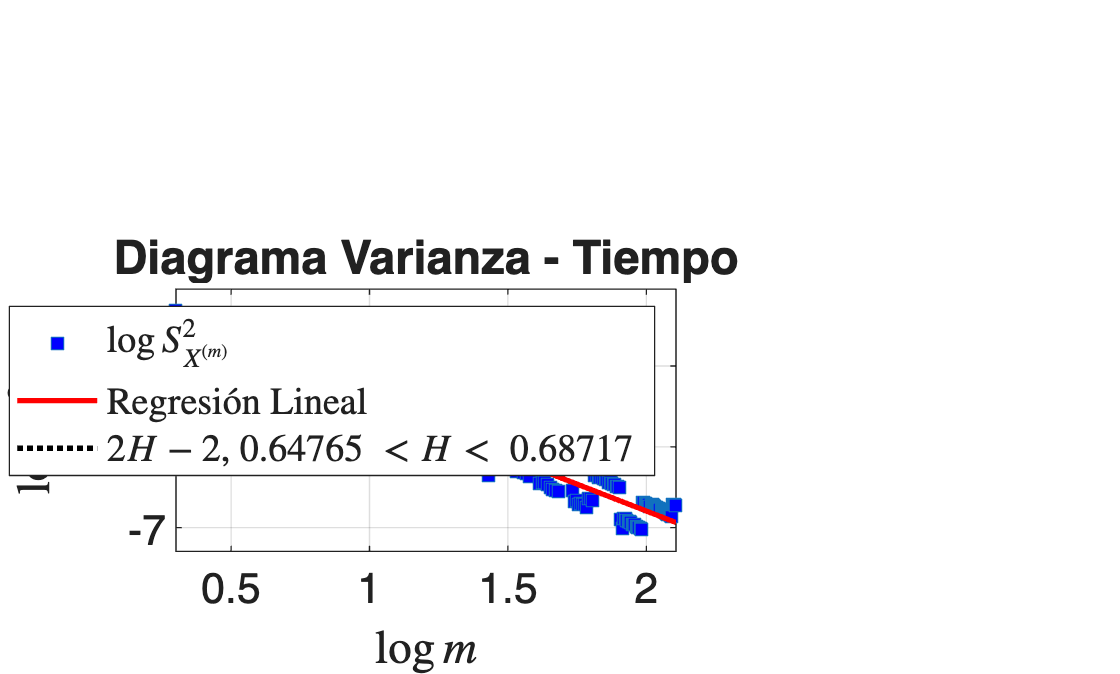

H1 = 0.6674

muestra = betamwm(Uoo,exponente,H);
figure(1);
H1 = vt(muestra)

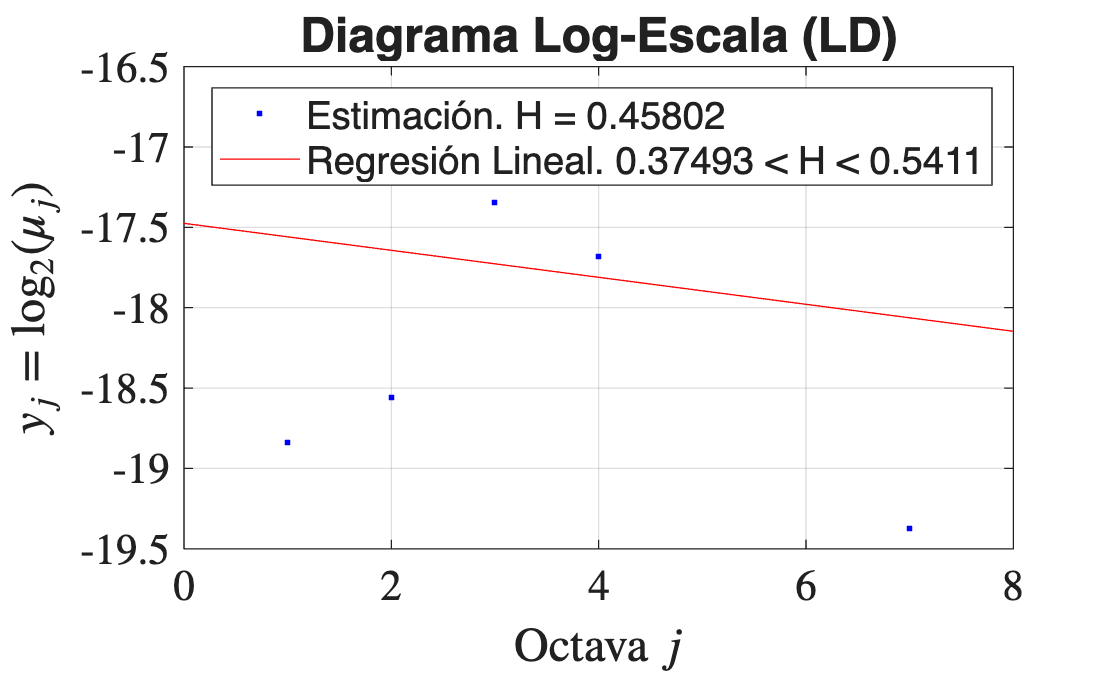

H2 = 0.4580

figure(2);
H2 = LD(muestra)

## wfbm

La función `wfbm` se puede emplear para generar secuencias discretas monofractales. Con tal propósito, se sugiere:

- Configurar longitudes en potencias de dos para que se puedan comparar los resultados con los generados por `betamwm`.

- El exponente de la potencia de dos debería ser de por lo menos 14.

- Una vez sintetizados los datos que genera `wfbm`, usar `diff`.

Por ejemplo:

H = 0.6; % Parámetro de Hurst seleccionado. 0.5<H<1.
exponente = 14; % Exponente de la potencia de 2. Mínimo 14 para tener más de 10000 datos.
2^exponente

ans = 16384

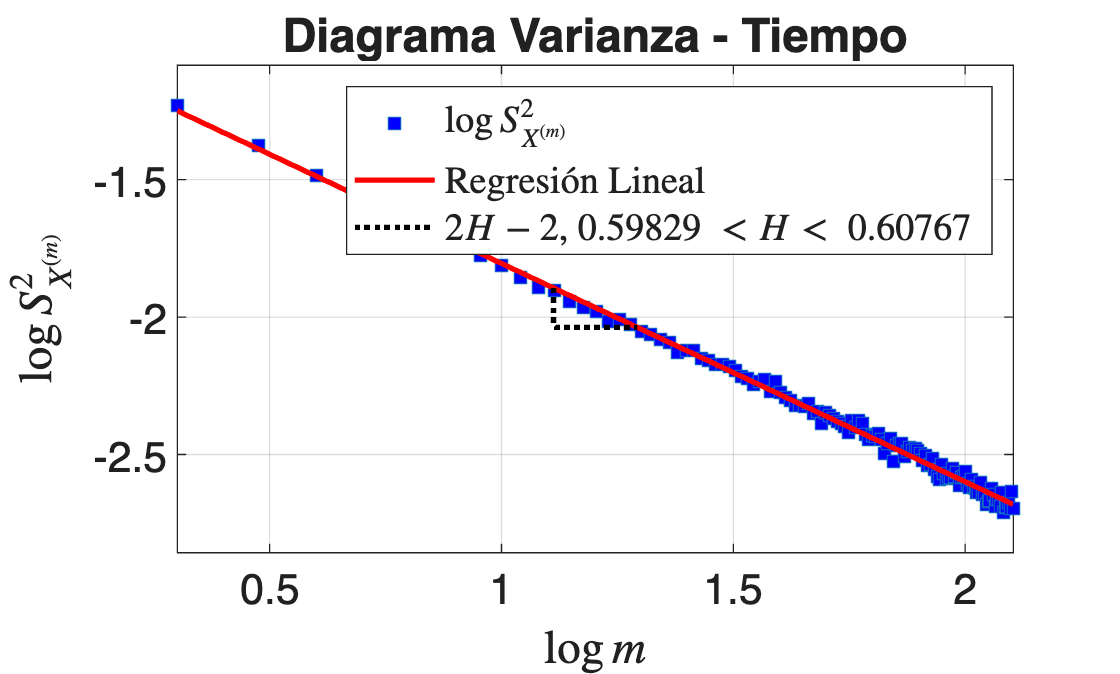

H1 = 0.6030

datos = wfbm(H,2^exponente);
muestra = diff(datos); % Secuencia discreta con LRD y monofractal.
figure(3);
H1 = vt(muestra)

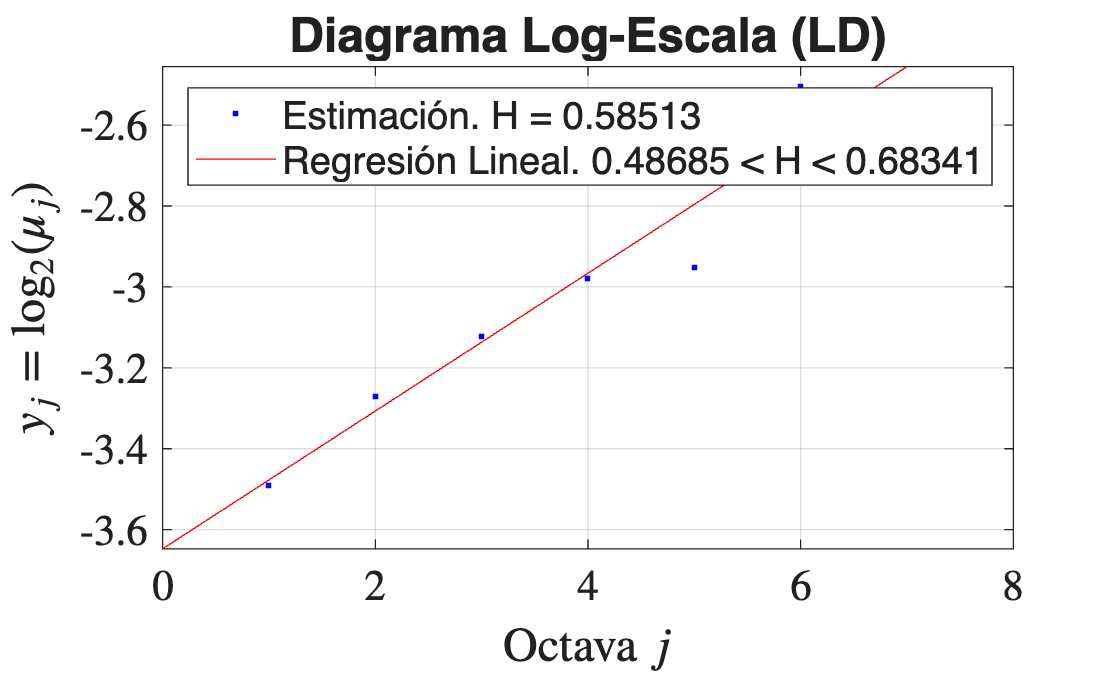

H2 = 0.5851

figure(4);
H2 = LD(muestra)

# Actividad 1

## Prueba de sesgo

haches = zeros(1,1000);

tic;
for n = 1:numel(haches)
    muestra = randn(1,100000);
    haches(n) = vt2(muestra);
end
toc;

Elapsed time is 9.726205 seconds.


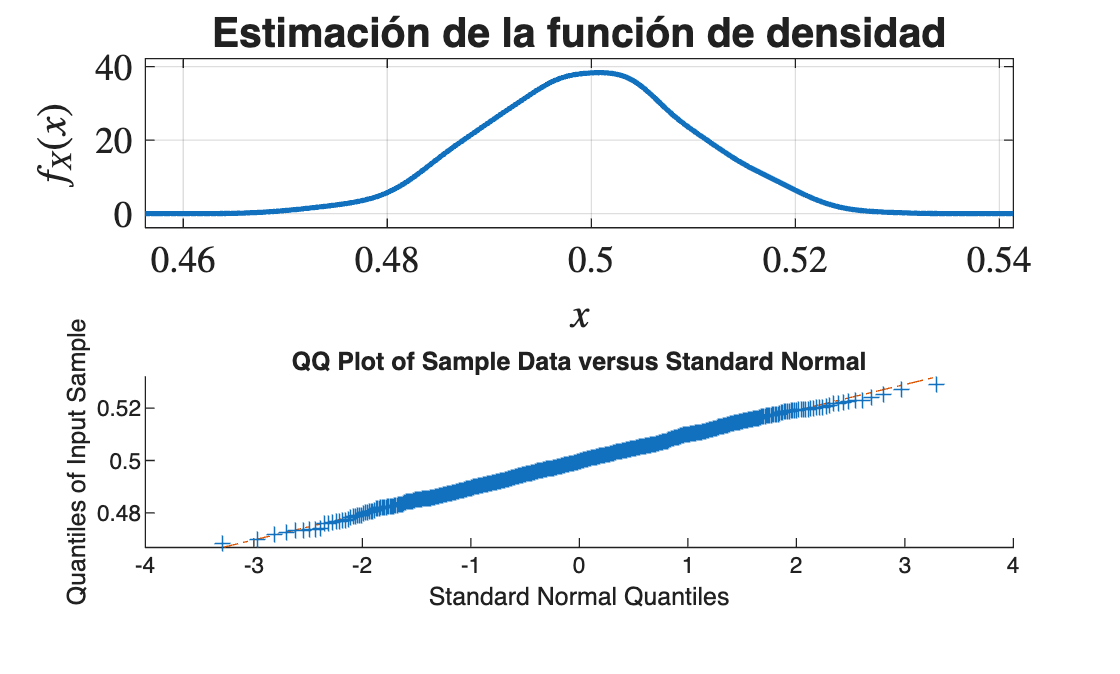

figure(5);
pdfcdfcontinua(haches,0);

subplot(2,1,2);
qqplot(haches);

mean(haches)

ans = 0.4996

normfit(haches)

ans = 0.4996

## Prueba de consistencia

tic;
m = 1;
varianzas = zeros(1,4); % Número de tamaños de muestras, lo pueden dejar así
figure(6);
for exponente = 10:2:16 % Exponentes con incrementos de 2. Empezar en 14 y terminar en 20
    haches = zeros(1,1000);
    for n = 1:numel(haches)
        muestra = randn(1,2^exponente);
        haches(n) = LD2(muestra); % Se debe ralizar la prueba para vt y LD
    end
    varianzas(m) = var(haches);
    m = m + 1;
    pdfcdfcontinua(haches,0);
    subplot(2,1,1);
    hold on;
end
toc;

Elapsed time is 2.649297 seconds.


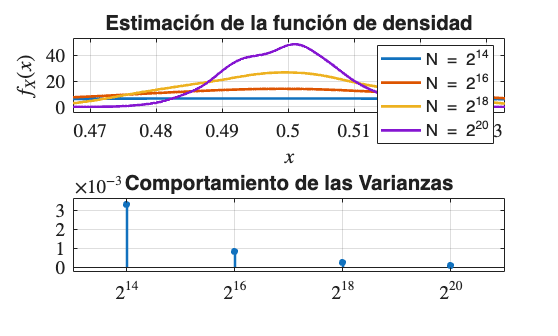

subplot(2,1,1);
legend('N = 2^{14}','N = 2^{16}','N = 2^{18}','N = 2^{20}'); % Se debe cambiar si son más de 4
hold off;
subplot(2,1,2);
superstem(1:4,varianzas,'Comportamiento de las Varianzas');
xticks(1:4);
xticklabels({'$2^{14}$','$2^{16}$','$2^{18}$','$2^{20}$'}); % Se debe cambiar si son más de 4

## Prueba de eficiencia

haches = zeros(1,1000);
tm = 100000; % Probar con varios tamaños de muestra (ej: 1000, 2000, 5000, 10000, 20000, 50000, 100000, ...)
tic;
parfor n = 1:numel(haches)
    muestra = randn(1,tm);
    haches(n) = vt2(muestra);
end
toc;

Elapsed time is 3.230816 seconds.


figure(7);
pdfcdfcontinua(haches,0);

subplot(2,1,1);
hold on;
subplot(2,1,2);
hold on;

haches = zeros(1,1000);

tic;
parfor n = 1:numel(haches)
    muestra = randn(1,tm);
    haches(n) = LD2(muestra);
end
toc;

Elapsed time is 0.545182 seconds.


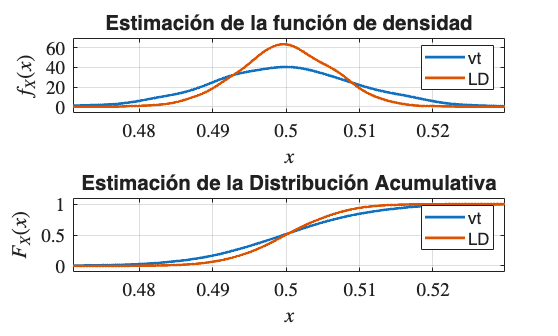

pdfcdfcontinua(haches,0);

subplot(2,1,1);
legend('vt','LD');
hold off;
subplot(2,1,2);
legend('vt','LD');
hold off;

## Parece ser que LD es mejor, pero...

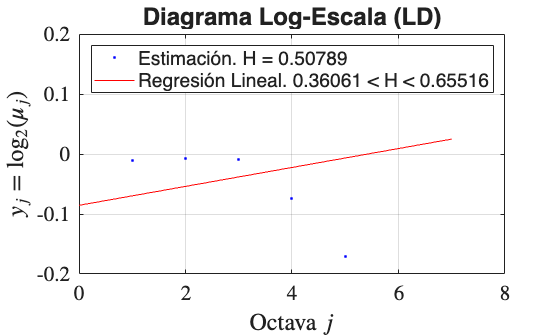

H = 0.5079

muestra = randn(1,7296);
figure(8);
H = LD(muestra)

# Actividad 2

## Con betamwm

haches = zeros(1,1000);

tic;
for n = 1:numel(haches)
    muestra = betamwm(1,14,0.9);
    haches(n) = vt2(muestra);
end
toc;

Elapsed time is 1.813484 seconds.


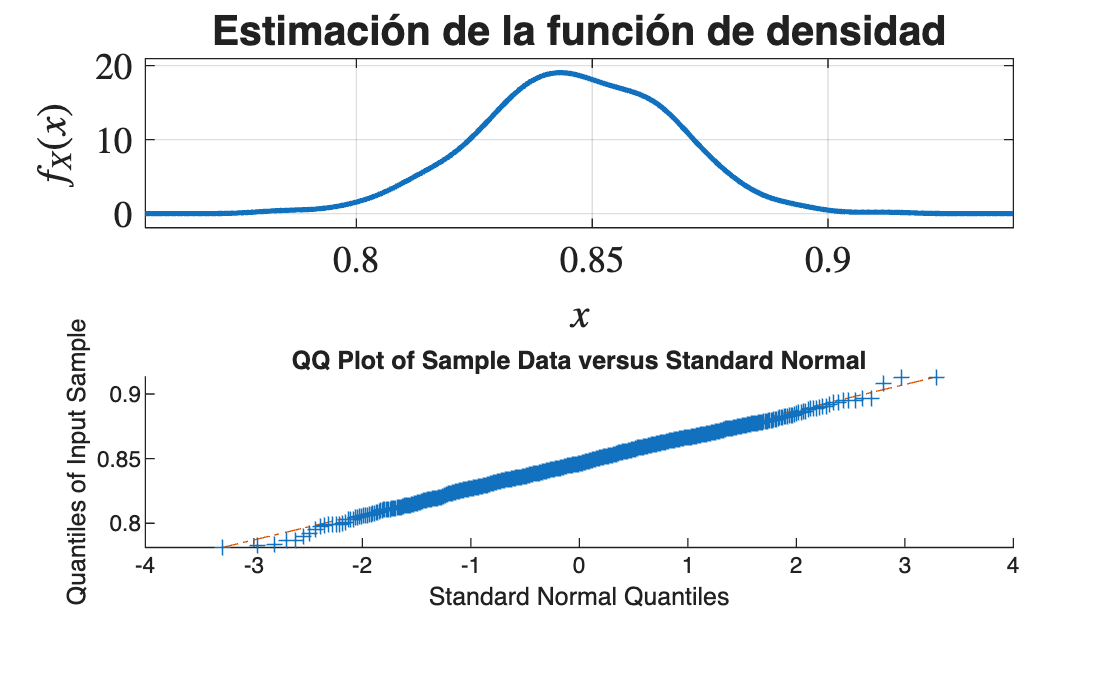

figure(9);
pdfcdfcontinua(haches,0);

subplot(2,1,2);
qqplot(haches);

mean(haches)

ans = 0.8464

normfit(haches)

ans = 0.8464

## Con wfbm

haches = zeros(1,1000);

tic;
for n = 1:numel(haches)
    datos = wfbm(0.9,2^14);
    muestra = diff(datos);
    haches(n) = vt2(muestra);
end
toc;

Elapsed time is 5.486644 seconds.


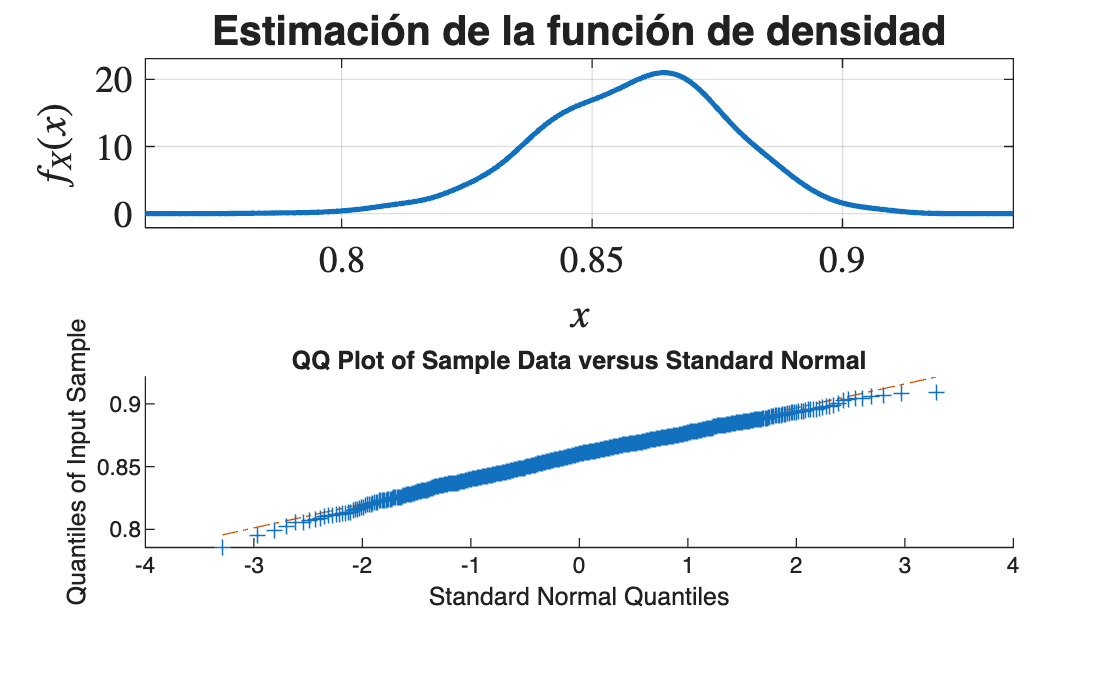

figure(10);
pdfcdfcontinua(haches,0);

subplot(2,1,2);
qqplot(haches);

mean(haches)

ans = 0.8585

normfit(haches)

ans = 0.8585

# Para la actividad 3

muestra = leerrinterval('ecgrrt/e0103.txt');
numel(muestra)

ans = 7296

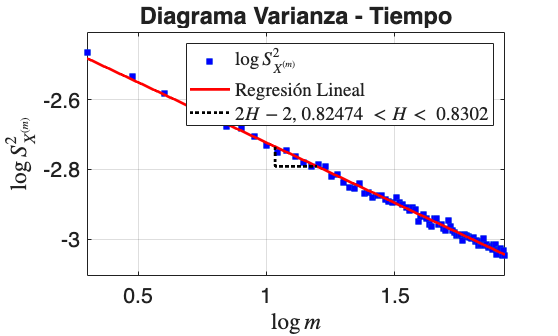

H = 0.8275

Hmin = 0.8247

Hmax = 0.8302

figure(11);
[H Hmin Hmax] = vt(muestra)

## Boxplot

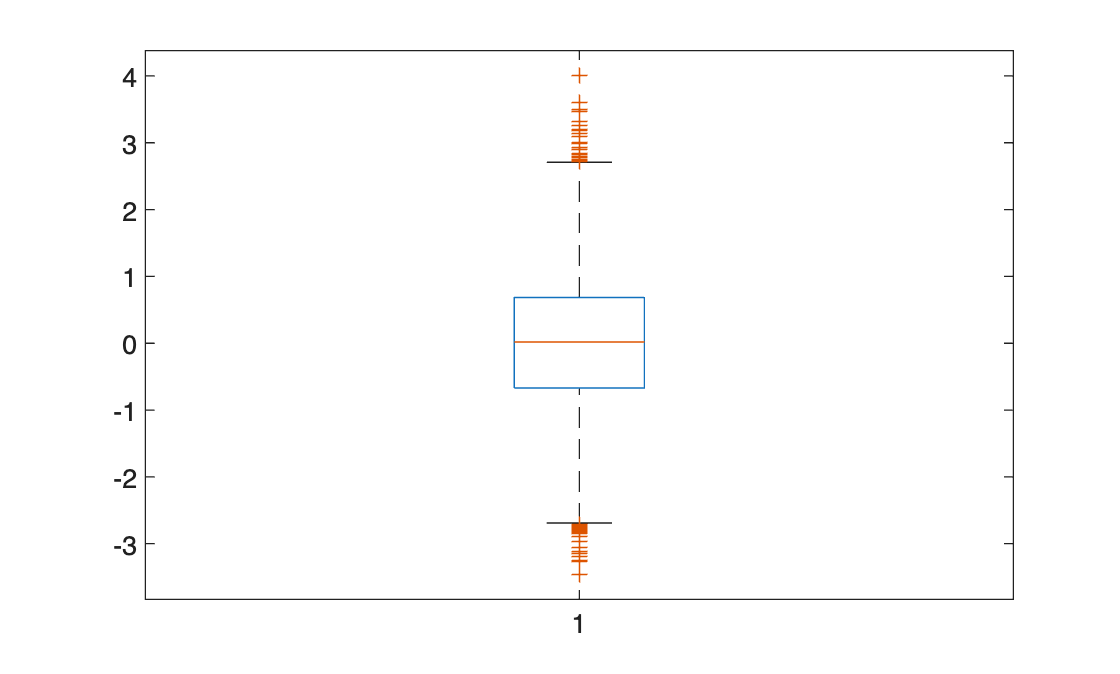

muestra = randn(1,10000);
figure(12);
boxplot(muestra);